# Thoery

`For the steady state case, we drop the temporal term and we are left with`


$$\frac{\partial^2\xi}{\partial x^2} + \frac{\partial^2\xi}{\partial y^2} = 0$$


`To solve this numerically we can use a ``meshgrid`` and use finite difference to replace the partial derivatives in the space coordinates. Applying central difference to both`


$$\frac{\Xi_{i-1,j}^{n} - 2\Xi_{i,j} +\Xi_{i+1,j}^{n}}{(\Delta x)^2} + \frac{\Xi_{i,j-1}^{n} - 2\Xi_{i,j} +\Xi_{i,j+1}^{n}}{(\Delta y)^2} = 0 $$


`If we take `$\Delta x = 0.1$ and $\Delta y = 0.05$ we get


$$\Xi_{i-1,j}^{n} + \Xi_{i+1,j}^{n} + 4\Xi_{i,j-1}^{n} + 4\Xi_{i,j+1}^{n} - 10\Xi_{i,j1}^{n} = 0 $$
         
$$i = 1,2,...9, j = 1,2,...19$$


clc; clear;

[x1, y1] = meshgrid(0:0.1:1, 0:0.05:1); 

%coefficient matrix
A1 = zeros(171);
A1 = A1 + diag(-10*ones(1, 171)) + 4*diag(ones(1,170), 1) + 4*diag(ones(1,170), -1);
A1 = A1 + diag(ones(1,171-19), 19) + diag(ones(1,171-19), -19);

for i = 19:19:152
    A1(i,i+1) = 0;
    A1(i+1,i) = 0;
end

%constant matrix
B1 = zeros(171, 1);
for i = 19:19:171
    B1(i) = -4;
end

[E1, ~] = mySOR(A1,B1,1.1);

# Plotting

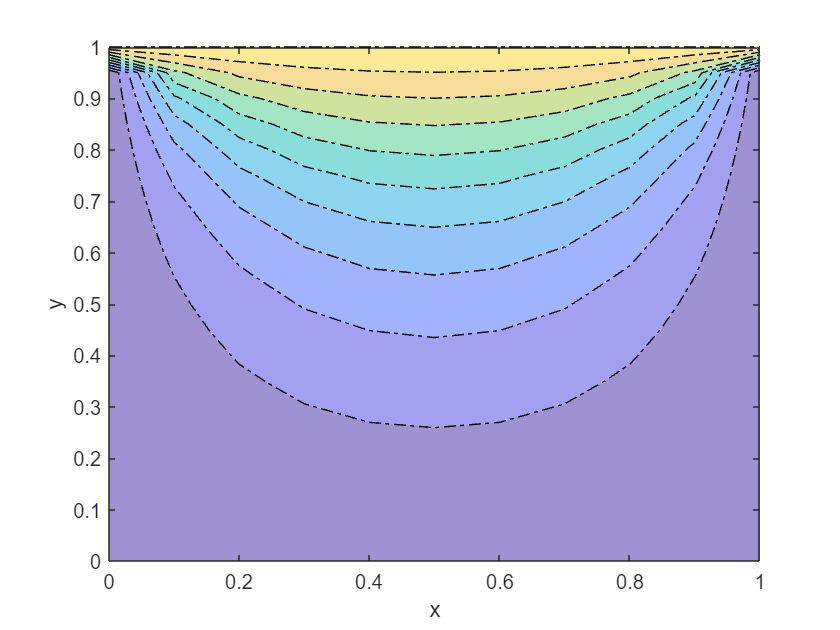

%solution matrix according to the shape of the mesh
Z1 = zeros(21, 11);
Z1(21, :) = 1;

for i = 1:9
    Z1(2:20, i+1) = E1(19*i-18:19*i);
end

contourf(x1, y1, Z1, LineStyle="-.", FaceAlpha=0.5 ,FaceColor="auto")
yticks(0:0.1:1)
xlabel('x')
ylabel('y')

# Iterative solver analysis

[~, iteration_jacobi] = myJacobi(A1,B1);
fprintf('It took %d iterations for the Jacobi solver to converge\n', iteration_jacobi);

It took 559 iterations for the Jacobi solver to converge



[~, iteration_seidal] = mySeidel(A1, B1);
fprintf('It took %d iterations for the Seidal solver to converge\n', iteration_seidal);

It took 302 iterations for the Seidal solver to converge



[~, iteration_SOR] = mySOR(A1, B1, 1.1);
fprintf('It took %d iterations for the SOR solver to converge\n', iteration_SOR);

It took 252 iterations for the SOR solver to converge


References:

[1] `Elementary Numerical Analysis, Kendall Atkinson, John ``\&`` Wiley Sons Inc, 2004`